clear; close all; clc;
load('contrast_data.mat');
whos

  Name          Size                       Bytes  Class     Attributes

  c             1x1                            8  double              
  f0            1x1                            8  double              
  fps           1x1                            8  double              
  pulses        1x4                          508  cell                
  rf          121x401x4x150            116450400  single              
  x             1x401                       3208  double              
  z             1x121                        968  double              



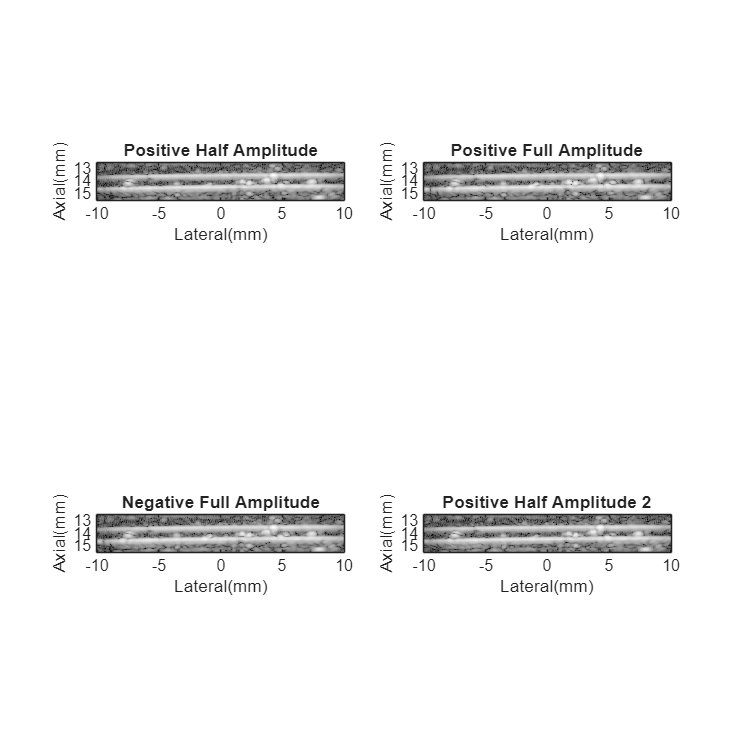

%single frame
frame = 1;
%Extract pulses
pulse_1 = squeeze(rf(:,:,1,frame)); %positive half amplitude
pulse_2 = squeeze(rf(:,:,2,frame)); %positive full amplitude
pulse_3 = squeeze(rf(:,:,3,frame)); %negative full amplitude
pulse_4 = squeeze(rf(:,:,4,frame)); %positive half amplitude 2

%convert RF to B-Mode
bModeImage = @(rfIm) 20*log10(abs(hilbert(rfIm))+eps);
% Convert each pulse to B-Mode images
bModePulse1 = bModeImage(pulse_1);
bModePulse2 = bModeImage(pulse_2);
bModePulse3 = bModeImage(pulse_3);
bModePulse4 = bModeImage(pulse_4);
%dynamic range
dr = [-60 0];
figure('Position',[20,20,1200,1200]);
% Display B-Mode images for each pulse
subplot(2,2,1)
imagesc(x*1000, z*1000, bModePulse1,max(bModePulse1(:)) + dr)
axis image; colormap gray
title('Positive Half Amplitude');
xlabel('Lateral(mm)')
ylabel('Axial(mm)')
subplot(2,2,2)
imagesc(x*1000, z*1000, bModePulse2, max(bModePulse2(:)) + dr)
axis image; colormap gray
title('Positive Full Amplitude');
xlabel('Lateral(mm)')
ylabel('Axial(mm)')
subplot(2,2,3)
imagesc(x*1000, z*1000, bModePulse3, max(bModePulse3(:)) + dr)
axis image; colormap gray
title('Negative Full Amplitude');
xlabel('Lateral(mm)')
ylabel('Axial(mm)')
subplot(2,2,4)
imagesc(x*1000, z*1000, bModePulse4, max(bModePulse4(:)) + dr)
axis image; colormap gray
title('Positive Half Amplitude 2');
xlabel('Lateral(mm)')
ylabel('Axial(mm)')

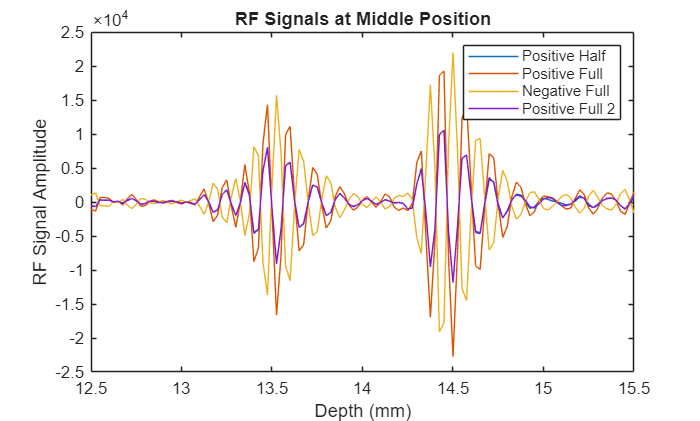

%Differences?


%Question aii
middle = round(length(x)/2);
%pick frame
t=1;
%Extract the four RF signals
% Extract the selected RF signals for the chosen frame
rfSignal1 = squeeze(rf(:,middle,1,t)); %positive half
rfSignal2 = squeeze(rf(:,middle,2,t)); %positive full
rfSignal3 = squeeze(rf(:,middle,3,t)); %negative full
rfSignal4 = squeeze(rf(:,middle,4,t)); %positive full 2

%plot
figure;
plot(z*1000, rfSignal1); hold on;
plot(z*1000, rfSignal2);
plot(z*1000, rfSignal3);
plot(z*1000, rfSignal4);
hold off;
xlabel('Depth (mm)');
ylabel('RF Signal Amplitude');
title('RF Signals at Middle Position');
legend('Positive Half', 'Positive Full', 'Negative Full', 'Positive Full 2');

%corrected amplitudes
% Correct the amplitudes of the RF signals
correctedSignal1 = rfSignal1*2;
correctedSignal2 = rfSignal2;
correctedSignal3 = -rfSignal3;
correctedSignal4 = rfSignal4*2;
% Plot corrected RF signals
figure;
plot(z*1000, correctedSignal1); hold on;
plot(z*1000, correctedSignal2);
plot(z*1000, correctedSignal3);
plot(z*1000, correctedSignal4);
hold off;
xlabel('Depth (mm)');
ylabel('Corrected RF Signal Amplitude');
title('Corrected RF Signals at Middle Position');
legend('Corrected Positive Half', 'Corrected Positive Full', 'Corrected Negative Full', 'Corrected Positive Full 2');

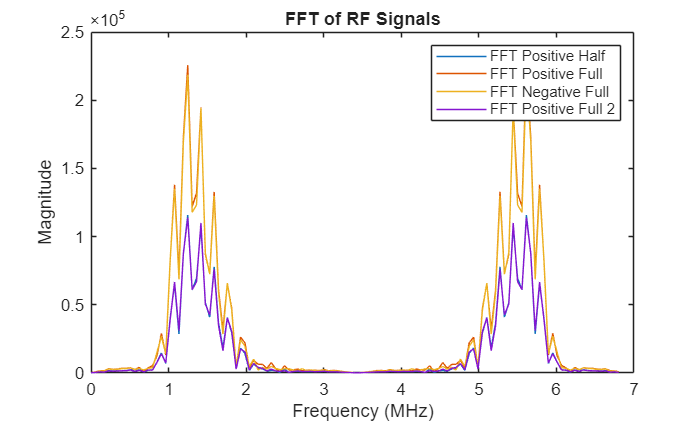

% question 2aiii
rf_fft1 = fft(rfSignal1);
rf_fft2 = fft(rfSignal2);
rf_fft3 = fft(rfSignal3);
rf_fft4 = fft(rfSignal4);

% fs = c/2*deltaz
dz = z(2) - z(1);
fs = 343/(2*dz);
N=length(rfSignal1);
frequency = (0:N-1)/N*fs;

%plot
figure;
plot(frequency/1e6, abs(rf_fft1)); hold on;
plot(frequency/1e6, abs(rf_fft2));
plot(frequency/1e6, abs(rf_fft3));
plot(frequency/1e6, abs(rf_fft4));
hold off;
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('FFT of RF Signals');
legend('FFT Positive Half', 'FFT Positive Full', 'FFT Negative Full', 'FFT Positive Full 2');

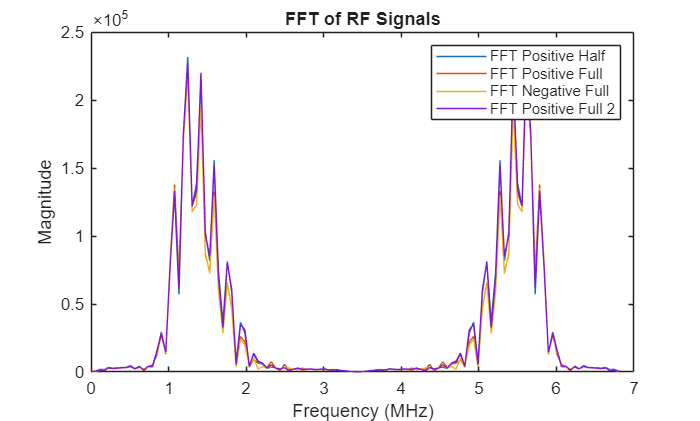

correctedrf_fft1 = fft(correctedSignal1);
correctedrf_fft2 = fft(correctedSignal2);
correctedrf_fft3 = fft(correctedSignal3);
correctedrf_fft4 = fft(correctedSignal4);

N=length(rfSignal1);
frequency = (0:N-1)/N*fs;

%plot
figure;
plot(frequency/1e6, abs(correctedrf_fft1)); hold on;
plot(frequency/1e6, abs(correctedrf_fft2));
plot(frequency/1e6, abs(correctedrf_fft3));
plot(frequency/1e6, abs(correctedrf_fft4));
hold off;
xlabel('Frequency (MHz)');
ylabel('Magnitude');
title('FFT of RF Signals');
legend('FFT Positive Half', 'FFT Positive Full', 'FFT Negative Full', 'FFT Positive Full 2');

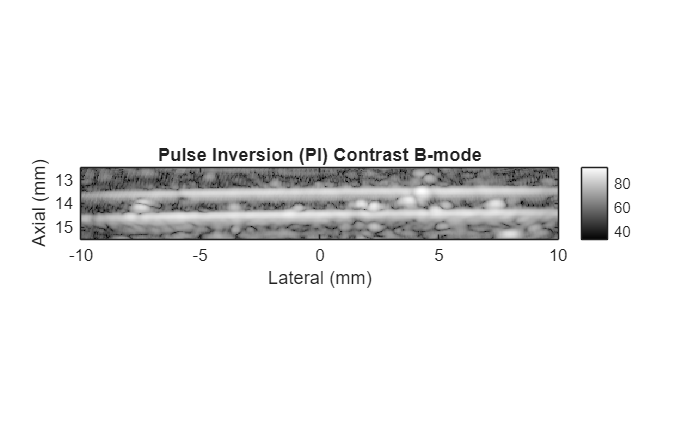

%Question bi
% 2D amplitude-corrected pulses
pulse1_corr = 2 * pulse_1;   % half → full
pulse2_corr = pulse_2;       % full
pulse3_corr = -pulse_3;      % flip sign
pulse4_corr = 2 * pulse_4;   % half → full

rf_PI = (pulse3_corr + pulse4_corr) / 2;

% B-mode image
bMode_PI = bModeImage(rf_PI);

figure;
imagesc(x*1e3, z*1e3, bMode_PI, max(bMode_PI(:)) + [-60 0]);
axis image; colormap gray;
xlabel('Lateral (mm)');
ylabel('Axial (mm)');
title('Pulse Inversion (PI) Contrast B-mode');
colorbar;

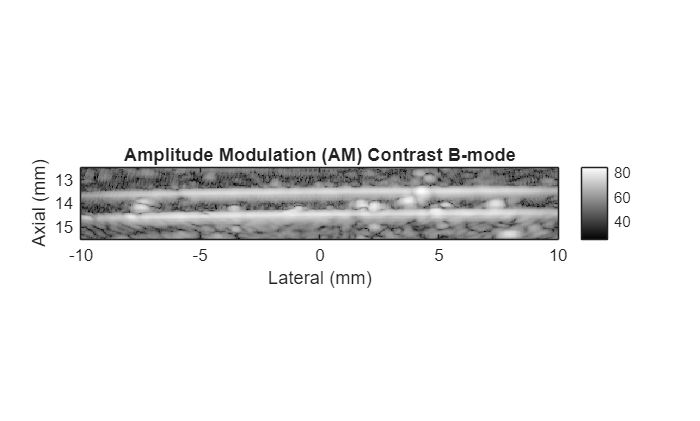


%Question bii
rf_AM = (pulse3_corr - pulse1_corr - pulse2_corr) / 3;

% B-mode image
bMode_AM = bModeImage(rf_AM);

figure;
imagesc(x*1e3, z*1e3, bMode_AM, max(bMode_AM(:)) + [-60 0]);
axis image; colormap gray;
xlabel('Lateral (mm)');
ylabel('Axial (mm)');
title('Amplitude Modulation (AM) Contrast B-mode');
colorbar;

%Question biii
rf_AMPI = (pulse4_corr + pulse1_corr + pulse2_corr) / 3;

% B-mode image
bMode_AMPI = bModeImage(rf_AMPI);

figure;
imagesc(x*1e3, z*1e3, bMode_AMPI, max(bMode_AMPI(:)) + [-60 0]);
axis image; colormap gray;
xlabel('Lateral (mm)');
ylabel('Axial (mm)');
title('AM + PI Contrast B-mode');
colorbar;


middle = round(length(x)/2);

% Single-pulse reference signal (positive full, corrected)
sig_full = pulse3_corr(:, middle);

% Contrast-mode signals
sig_PI   = rf_PI(:, middle);
sig_AM   = rf_AM(:, middle);
sig_AMPI = rf_AMPI(:, middle);

% FFTs
H_full = fft(sig_full);
H_PI   = fft(sig_PI);
H_AM   = fft(sig_AM);
H_AMPI = fft(sig_AMPI);

N  = length(sig_full);
dz = z(2) - z(1);
fs = c / (2*dz);                    % RF sampling frequency
f  = (0:N-1)/N * fs;

% dB spectra normalized by single-pulse spectrum (per frequency)
PI_dB   = 20*log10( abs(H_PI)./abs(H_full) + eps );
AM_dB   = 20*log10( abs(H_AM)./abs(H_full) + eps );
AMPI_dB = 20*log10( abs(H_AMPI)./abs(H_full) + eps );

figure;
plot(f/1e6, PI_dB); hold on;
plot(f/1e6, AM_dB);
plot(f/1e6, AMPI_dB);
hold off;
xlabel('Frequency (MHz)');
ylabel('Normalized Magnitude (dB)');
title('Contrast-mode Spectra (normalized by single-pulse spectrum)');
legend('Pulse inversion','Amplitude modulation','AM + PI','Location','Best');
grid on;

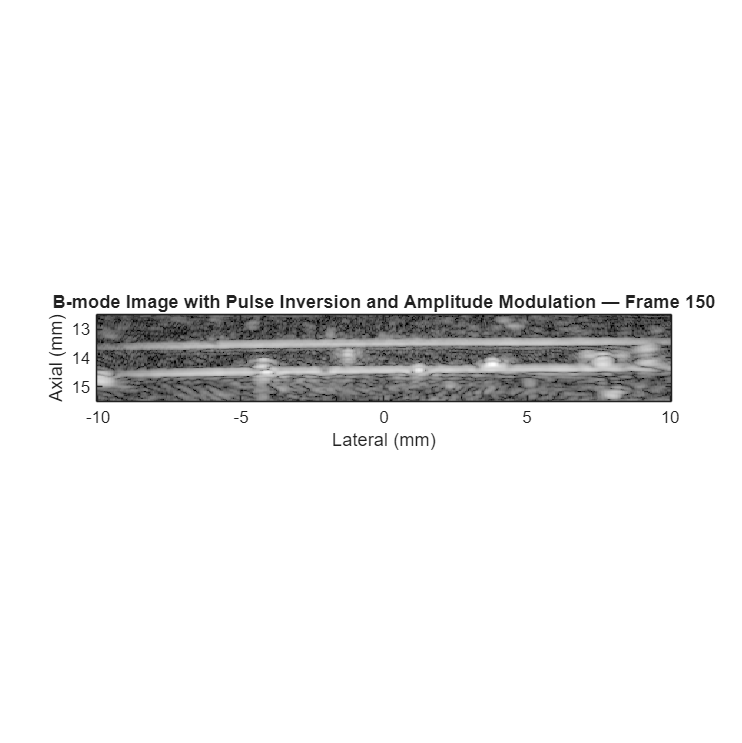

clear; close all; clc;
%3a
load('contrast_data.mat');

bModeImage = @(rfIm) 20*log10(abs(hilbert(rfIm)) + eps);
dr = [-60 0];
nFrames = size(rf, 4);

v = VideoWriter('ContrastMovie_PIAM.avi');
v.FrameRate = 15;
open(v);

figure('Position', [100 100 600 600]);

for t = 1:nFrames
    pulse1_AM = squeeze(rf(:,:,1,t));
    pulse3    = squeeze(rf(:,:,3,t));
    pulse4_AM = squeeze(rf(:,:,4,t));

    RF_PIAM = (pulse3 + pulse1_AM + pulse4_AM)/3;
    Bmode_PIAM = bModeImage(RF_PIAM);
    maxVal = max(Bmode_PIAM(:));

    imagesc(x*1000, z*1000, Bmode_PIAM, maxVal + dr);
    axis image; colormap gray;
    xlabel('Lateral (mm)');
    ylabel('Axial (mm)');
    title(sprintf('B-mode Image with Pulse Inversion and Amplitude Modulation — Frame %d', t));

    frame = getframe(gcf);
    writeVideo(v, frame);
end


close(v);
disp('Movie saved as ContrastMovie_PIAM.avi');

Movie saved as ContrastMovie_PIAM.avi


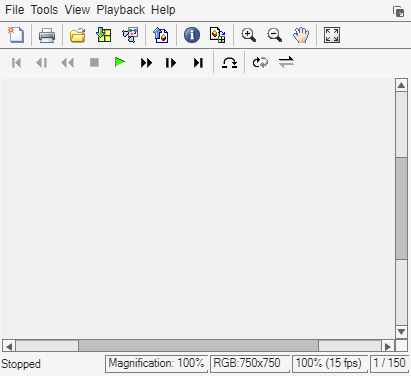

implay('ContrastMovie_PIAM.avi');

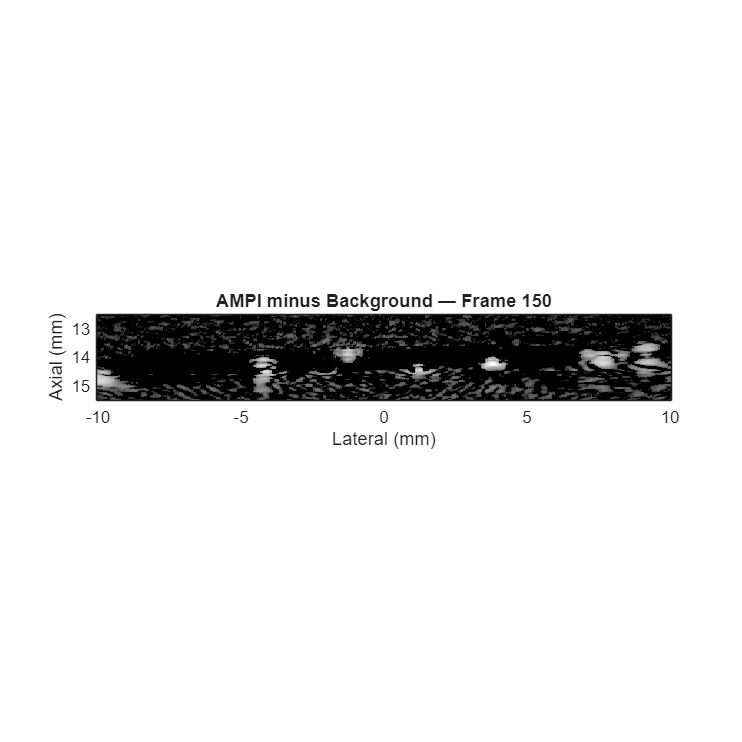

%3b
nFrames = size(rf,4);
nz = length(z);
nx = length(x);
dr = [-60 0];

envStack = zeros(nz, nx, nFrames);

for t = 1:nFrames
    pulse1_AM = squeeze(rf(:,:,1,t));
    pulse3    = squeeze(rf(:,:,3,t));
    pulse4_AM = squeeze(rf(:,:,4,t));

    RF_PIAM = (pulse3 + pulse1_AM + pulse4_AM) / 3;

    envStack(:,:,t) = abs(hilbert(RF_PIAM));
end

meanEnv = mean(envStack, 3);

envStack_sub = zeros(size(envStack));
for t = 1:nFrames
    envStack_sub(:,:,t) = envStack(:,:,t) - meanEnv;
end

v2 = VideoWriter('ContrastMovie_PIAM_bgSub.avi');
v2.FrameRate = 15;
open(v2);

figure('Position', [200 200 600 600]);

for t = 1:nFrames
    env_sub = max(envStack_sub(:,:,t), 0);
    bMode_sub = 20*log10(env_sub + eps);
    maxVal_sub = max(bMode_sub(:));

    imagesc(x*1e3, z*1e3, bMode_sub, maxVal_sub + dr);
    axis image; colormap gray;
    xlabel('Lateral (mm)');
    ylabel('Axial (mm)');
    title(sprintf('AMPI minus Background — Frame %d', t));

    frame = getframe(gcf);
    writeVideo(v2, frame);
end

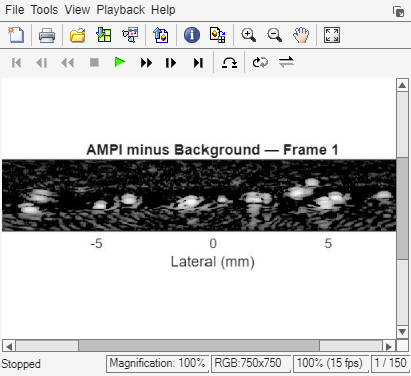


close(v2);
implay('ContrastMovie_PIAM_bgSub.avi');